# Laboratorio 2 - Modelo geométrico inverso

**Grupo 8**

Ardila, Juan Andrés

López, Nicolás

Rojas, Juan Camilo

Nuestro robot: Fanuc R-2000iC/125L

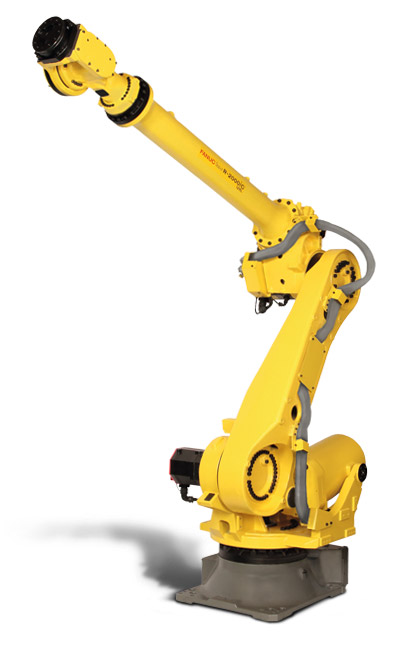

- Determine el modelo geométrico inverso del robot asignado haciendo uso de la metodología explicada en clase. Haga una descripción detallada del proceso haciendo uso de imágenes y dibujos que ayuden visualizar de dónde provienen las ecuaciones encontradas.

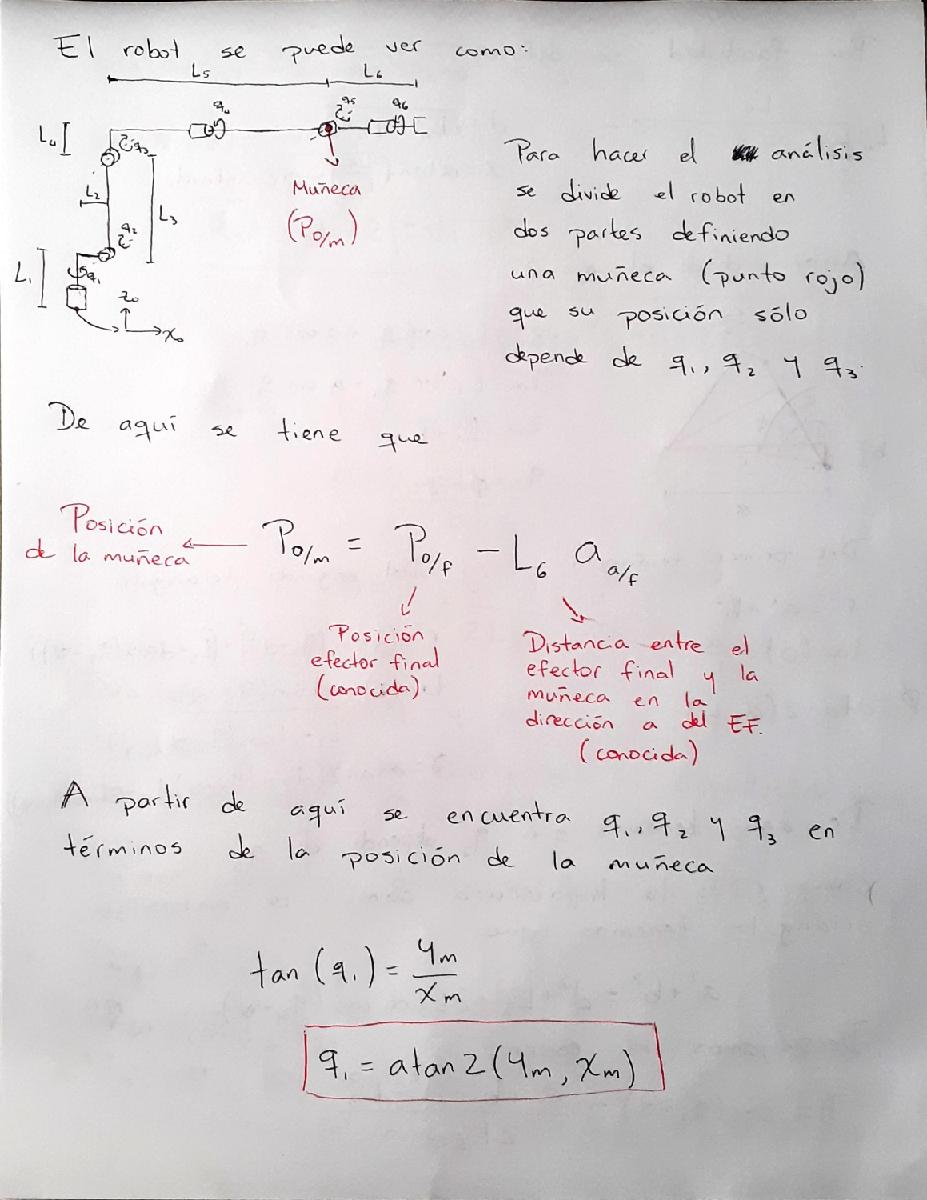

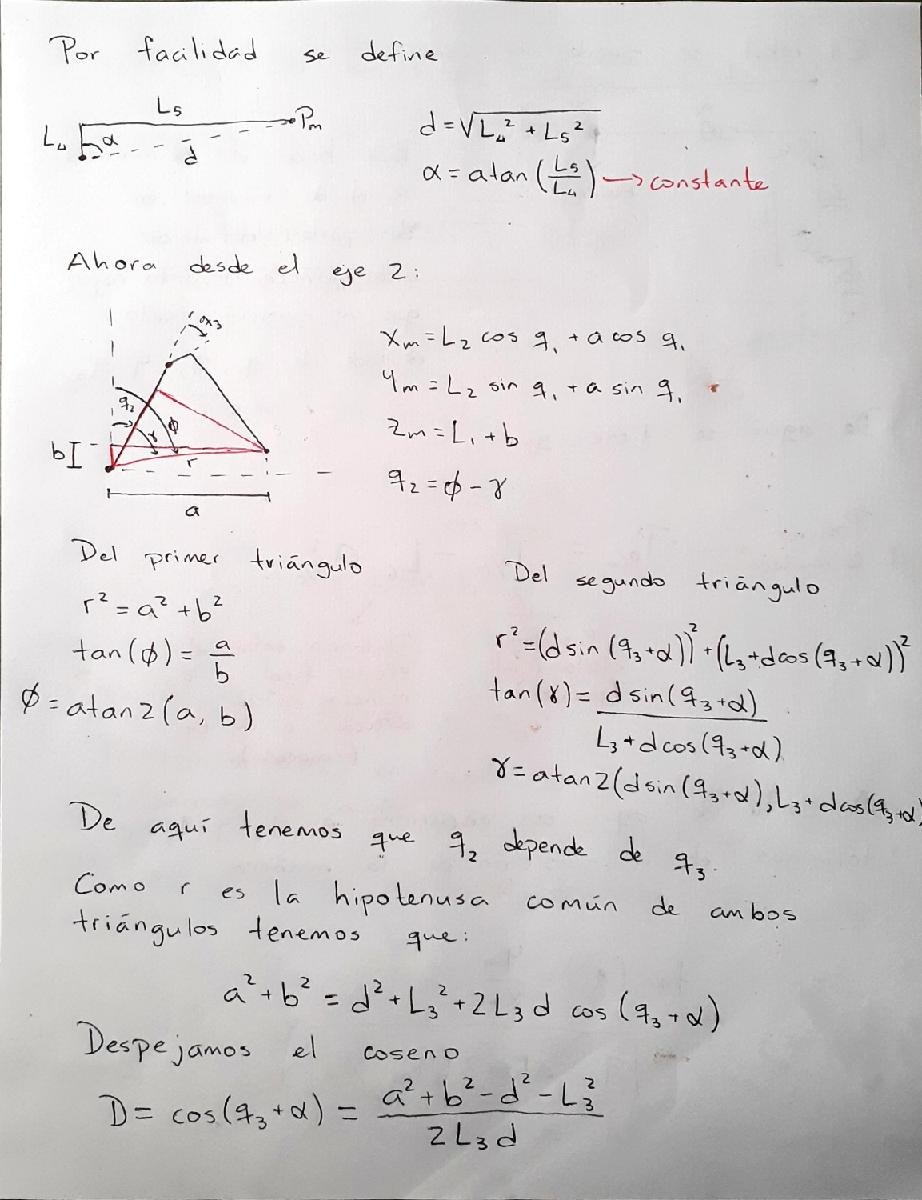

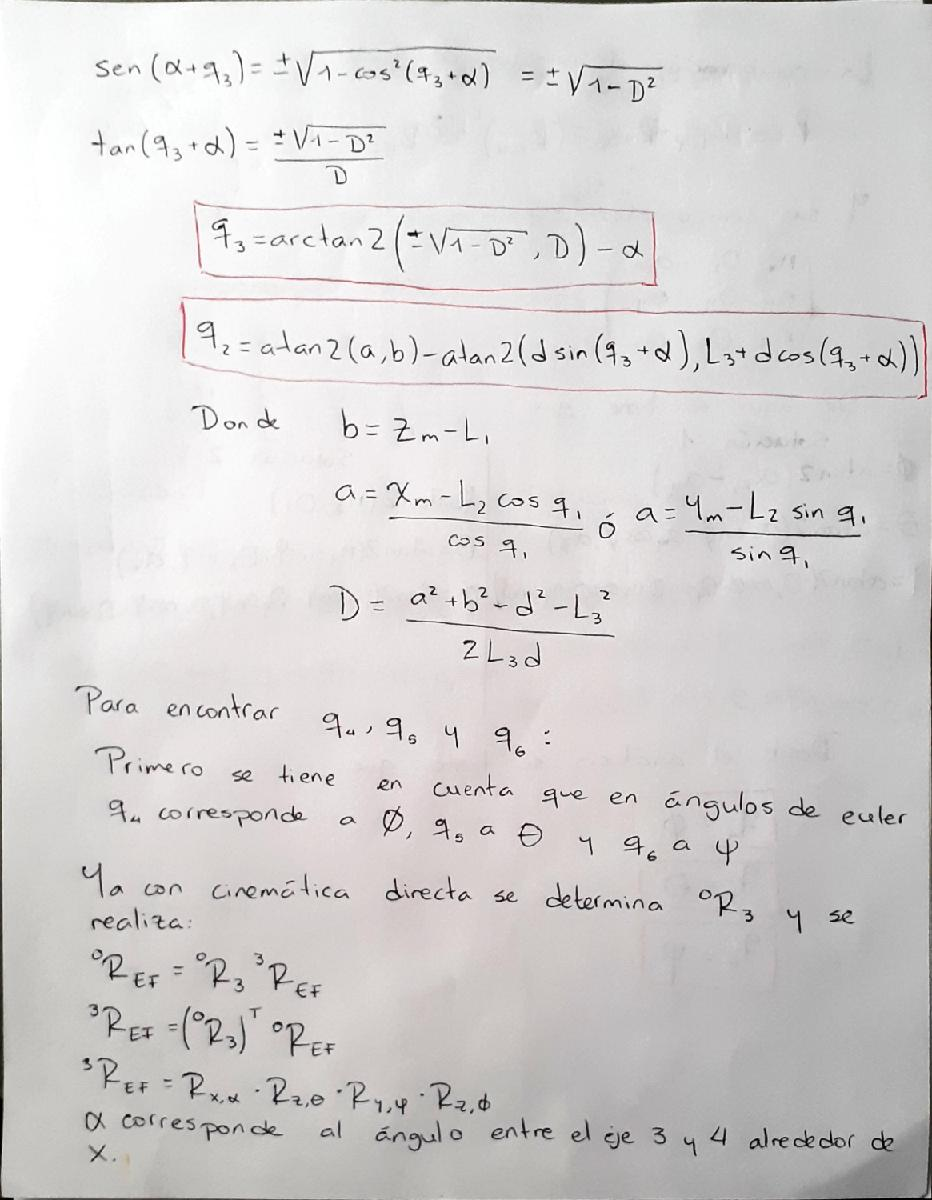

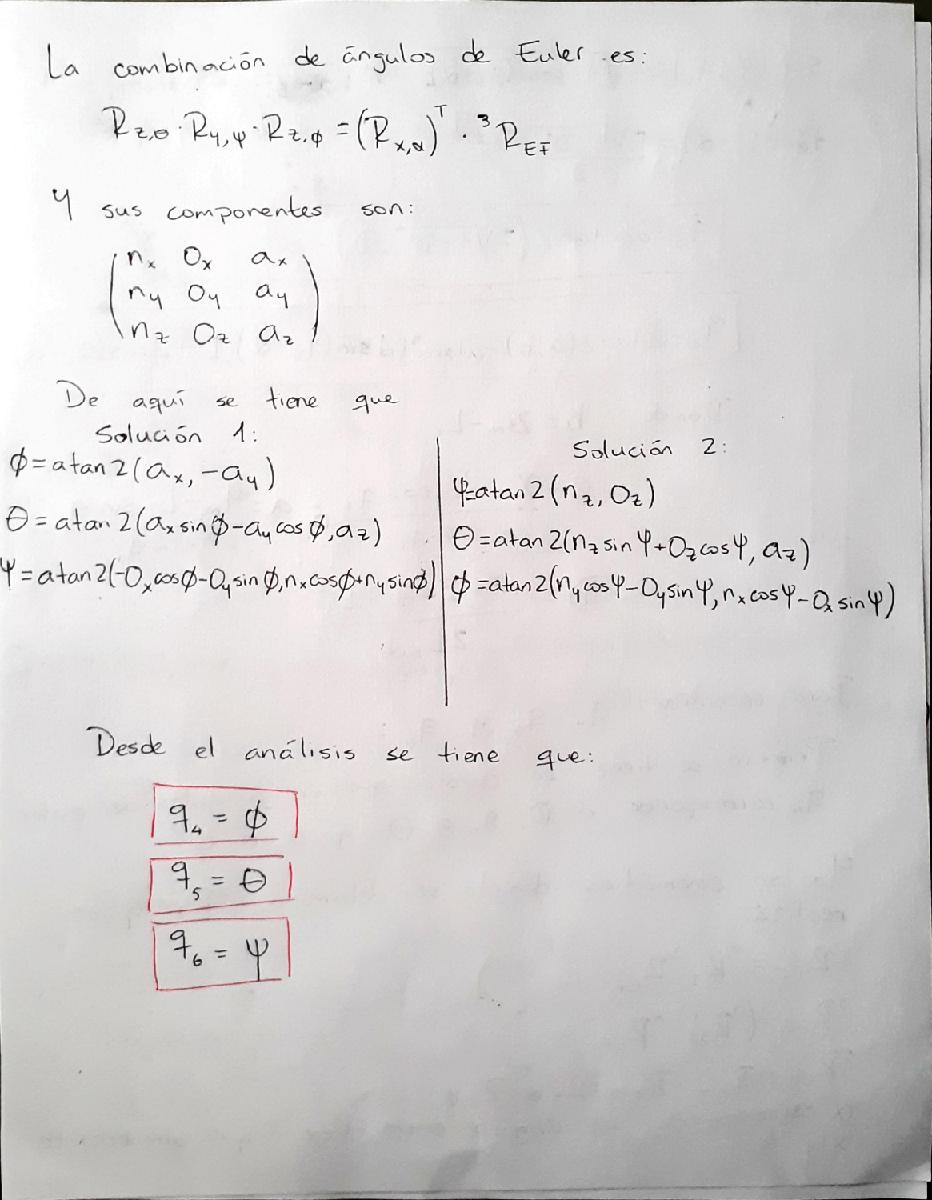

2. En las soluciones de la inversa incluya consideraciones respecto a multiplicidad de soluciones.

Existen al final del análisis dos soluciones para los ángulos de la muñeca, por lo que se puede tener codo arriba y codo abajo. A su vez, si vemos la solución anterior a la muñeca podemos ver que la variable «a» tiene dos soluciones, por lo que puede ser hombro izquierda y hombro derecha. De esta manera tenemos en total 4 soluciones: codo arriba hombro derecha, codo arriba hombro izquierda, codo abajo hombro derecha y codo abajo hombro izquierda.

A continuación veremos el robot como se describió en el laboratorio pasado:

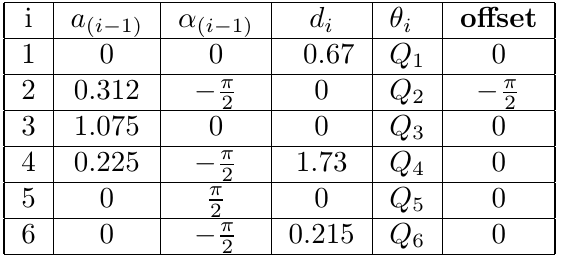

clear
L(1) = Link('revolute','alpha',0,    'a', 0,    'd',0.67, 'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha',-pi/2,'a', 0.312,'d',0,    'offset',-pi/2,...
    'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha',0,    'a', 1.075,'d',0,    'offset',0,  ...
    'modified', 'qlim',[-pi pi]);
L(4) = Link('revolute','alpha',-pi/2,'a', 0.225,'d',1.73, 'offset',0, ...
    'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha',pi/2,  'a', 0,   'd',0,    'offset',0, ...
    'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha',-pi/2, 'a', 0,   'd',0.215,'offset',0, ...
    'modified', 'qlim',[-pi pi]);

syms Q1 Q2 Q3 Q4 Q5 Q6 real
A_0_1 = L(1).A(0)

A_0_1 =     1.0000         0         0         0
         0    1.0000         0         0
         0         0    1.0000    0.6700
         0         0         0    1.0000


A_1_2 = L(2).A(0)

A_1_2 =     0.0000    1.0000         0    0.3120
   -0.0000    0.0000    1.0000         0
    1.0000   -0.0000    0.0000         0
         0         0         0    1.0000


A_2_3 = L(3).A(0)

A_2_3 =     1.0000         0         0    1.0750
         0    1.0000         0         0
         0         0    1.0000         0
         0         0         0    1.0000


A_3_4 = L(4).A(0)

A_3_4 =     1.0000         0         0    0.2250
         0    0.0000    1.0000    1.7300
         0   -1.0000    0.0000    0.0000
         0         0         0    1.0000


A_4_5 = L(5).A(0)

A_4_5 =     1.0000         0         0         0
         0    0.0000   -1.0000         0
         0    1.0000    0.0000         0
         0         0         0    1.0000


A_5_6 = L(6).A(0)

A_5_6 =     1.0000         0         0         0
         0    0.0000    1.0000    0.2150
         0   -1.0000    0.0000    0.0000
         0         0         0    1.0000



T_0_6 = A_0_1 * A_1_2 * A_2_3 * A_3_4 * A_4_5 * A_5_6 *eye(4);

Robot = SerialLink(L,'name','R_{Fanuc}')

 
Robot = 
 
R_{Fanuc} (6 axis, RRRRRR, modDH, fastRNE)                       
                                                                 
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|       0.67|          0|          0|          0|
|  2|         q2|          0|      0.312|     -1.571|     -1.571|
|  3|         q3|          0|      1.075|          0|          0|
|  4|         q4|       1.73|      0.225|     -1.571|          0|
|  5|         q5|          0|          0|      1.571|          0|
|  6|         q6|      0.215|          0|     -1.571|          0|
+---+-----------+-----------+-----------+-----------+-----------+
                                                                 
grav =    0  base = 1  0  0  0   tool =  1  0  0  0              
          0         0  1  0  0           0  1  0  0            

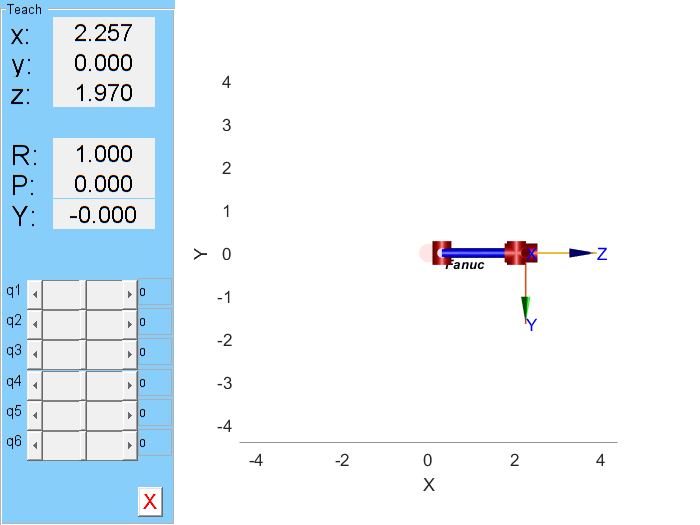

figure(1)
Robot.teach();

3.  Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el Toolbox explique:

- ¿Cuál es la diferencia entre estas funciones?

El Toolbox ofrece varias funciones relacionadas con cinemática inversa. Entre ellas se incluyen:

SerialLink.ikcon

Cinemática inversa numérica con límites de articulación

q = R.ikcon(T) son las coordenadas de articulación (1×N) que corresponden a la pose del end-effector T (4 × 4) la cual es una transformada homogénea. 

[q,err] = robot.ikcon(T) es como la anterior pero devuelve err el cual es el valor final (escalar) de la función objetivo.

[q,err,exitflag] = robot.ikcon(T) es como la anterior pero también devuelve el estado exitflag de fmincon. 

[q,err,exitflag] = robot.ikcon(T, q0) es como la anterior pero especifica las coordenadas de la articulación inicial q0 usada para la minimización. 

[q,err,exitflag] = robot.ikcon(T, q0, options) es como la anterior pero especifica las opciones para que fmincon use.

SerialLink.ikine 

Cinemática inversa numérica

q = R.ikine(T) son las coordenadas de articulación (1×N) que corresponden a la pose del end-effector T (4 × 4) la cual es una transformada homogénea. 

q = R.ikine(T, q0, options) especifica las coordenadas iniciales estimadas de la articulación. Este método se puede utilizar para robots con 6 o más GDL. 

SerialLink.ikine3 

Cinemática inversa para robots de 3 ejes sin muñeca

q = R.ikine3(T) son las coordenadas de articulación (1×N) que corresponden a la pose del end-effector T representada por la transformada homogénea. Ésta es una solución analítica para un robot de 3 ejes (así como las primeras 3 articulaciones de un robot como el Puma 560). 

q = R.ikine3(T, config) es como la anterior pero especifica la configuración del brazo en un string que contiene uno o más de los siguientes códigos: 

‘l’ brazo a la izquierda (default) 

‘r’ brazo a la derecho

‘u’ codo arriba (default) 

‘d’ codo abajo

SerialLink.ikine6s 

Cinemática inversa analítica

q = R.ikine6s(T) son las coordenadas de articulación (1 × N) que corresponden a la pose del end-effector T representada por una transformada homogénea SE(3) (4 × 4). Ésta es una solución analítica para un robot de 6 ejes con una muñeca esférica (la forma más común de brazos robóticos industriales).

SerialLink.ikine_sym 

Cinemática inversa simbólica

q = R.IKINE SYM(k, options) es una matriz de celdas (C ×1) de soluciones de cinemática inversa del objeto SerialLink del ROBOT. las celdas de q representan las configuraciones posibles. Cada celda de q es un vector (N × 1), y el elemento J son las expresiones simbólicas para el ángulo de articulación J-ésimo. 

SerialLink.ikinem 

Cinemática inversa numérica por minimización

q = R.ikinem(T) son las coordenadas de articulación que corresponden a la pose del end-effector T la cual es una transformada homogénea. 

q = R.ikinem(T, q0, options) especifica un estimado inicial de las coordenadas de la articulación. 

SerialLink.ikunc 

Manipulador inverso numérico sin límites de articulación

q = R.ikunc(T) son las coordenadas de articulación (1×N) correspondientes a la pose del end-effector T (4×4) la cual es una transformada homogénea, y N es el número de articulaciones del robot.

[q,err] = robot.ikunc(T) es como la anterior pero también devuelve err el cual es el valor final (escalar) de la función objetivo. 

[q,err,exitflag] = robot.ikunc(T) es como la anterior pero también devuelve el estado exitflag de fminunc. 

[q,err,exitflag] = robot.ikunc(T, q0)es como la anterior pero especifica las coordenadas iniciales de la articulación q0 usadas para la minimización. 

[q,err,exitflag] = robot.ikunc(T, q0, options) es como la anterior pero especifica las opciones que fminunc puede usar.

- ¿Cuál debe usar para su robot y por qué? (Revise la documentación del Toolbox)

%q = Robot.ikine6s(T_0_6)

4. Haga uso del RST para hallar la cinemática inversa de su robot asignado y compruebe los resultados anteriores.

Utilizando el RST

Creamos el robot:

robot = rigidBodyTree;

Creamos los eslabones (objetos sólidos):

body1 = rigidBody('body1'); 
body2 = rigidBody('body2'); 
body3 = rigidBody('body3'); 
body4 = rigidBody('body4'); 
body5 = rigidBody('body5'); 
body6 = rigidBody('body6'); 
bodyEndEffector=rigidBody('endeffector');

Se crean las uniones entre los eslabones:

jnt1 = rigidBodyJoint('jnt1','revolute');
jnt2 = rigidBodyJoint('jnt2','revolute');
jnt3 = rigidBodyJoint('jnt3','revolute');
jnt4 = rigidBodyJoint('jnt4','revolute');
jnt5 = rigidBodyJoint('jnt5','revolute');
jnt6 = rigidBodyJoint('jnt6','revolute');

Se definen las MTH entre cada eslabón y se hace el ensamble:

%body1
tform1 = transl(0, 0, 0.67);
setFixedTransform(jnt1,tform1); 
body1.Joint = jnt1;
addBody(robot,body1,'base')

%body2
tform2 = transl(0.312, 0, 0)*trotx(-pi/2)*trotz(-pi/2);
setFixedTransform(jnt2,tform2);
%setFixedTransform(jnt2,dhparams(2,:),'dh'); 
body2.Joint = jnt2;
addBody(robot,body2,'body1')

%body3
tform3 = transl(1.075, 0, 0);
setFixedTransform(jnt3,tform3);
body3.Joint = jnt3;
addBody(robot,body3,'body2')

%body4
tform4 = transl(0.225, 1.73, 0)*trotx(-pi/2);
setFixedTransform(jnt4,tform4);
body4.Joint = jnt4;
addBody(robot,body4,'body3')

%body5
tform5 = transl(0, 0, 0)*trotx(pi/2);
setFixedTransform(jnt5,tform5);
body5.Joint = jnt5;
addBody(robot,body5,'body4')

%body6
tform6 = transl(0, 0.215, 0)*trotx(-pi/2);
setFixedTransform(jnt6,tform6);
body6.Joint = jnt6;
addBody(robot,body6,'body5')

%endEffector
tform7 = trvec2tform([0 0 0]);
setFixedTransform(bodyEndEffector.Joint,tform7);
addBody(robot,bodyEndEffector,'body6')


gik = generalizedInverseKinematics;
gik.RigidBodyTree = robot;
gik.ConstraintInputs = {'position','aiming'};
posTgt = constraintPositionTarget('endeffector');
posTgt.TargetPosition = [2.257 0 1.97];
aimCon = constraintAiming('endeffector');
aimCon.TargetPoint = [1 0 0];
q0 = homeConfiguration(robot); % Initial guess for solver
[q,solutionInfo] = gik(q0,posTgt,aimCon)

q = 1×6 struct array with fields:
    JointName
    JointPosition


solutionInfo = struct with fields:
              Iterations: 163
       NumRandomRestarts: 3
    ConstraintViolations: [1×2 struct]
                ExitFlag: 7
                  Status: 'success'


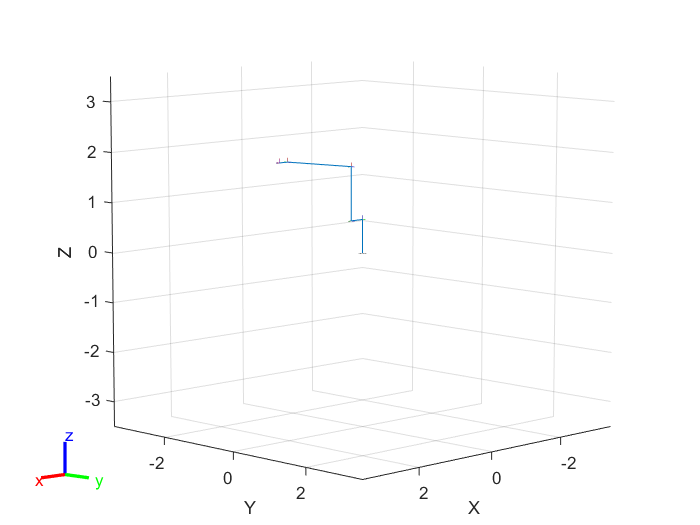


figure(2)
show(robot,homeConfiguration(robot));

6. Compruebe mediante su modelo geométrico inverso la configuración del robot para las posturas de la herramienta halladas en el anterior laboratorio, tales como puntos de calibración.

clear
%Unidades en metros
L1 = 0.67;
L2 = 0.312
L3 = 1.075
L4 = 0.225;
L5 = 1.730;
L6 = 0.215;
x = 1.92;
y = 0;
z = 2.257;
pos_final = [x y z]'
yaw = pi;
pitch = -pi/2;
roll = 0;
rot = rotz(yaw)*roty(pitch)*rotz(roll);
mth = [rot pos_final; 0 0 0 1]

pos_m = pos_final - rot*[0 0 1]'.*L6;
x_m = pos_m(1);
y_m = pos_m(2);
z_m = pos_m(3);
q1 = atan2(y_m,x_m)
if q1 == pi
    a = (y_m - L2*sin(q1))/sin(q1)
else 
    a = (x_m - L2*cos(q1))/cos(q1)
end
b = z_m - L1
d = sqrt((L4^2)+(L5^2))
alpha = atan(L5/L4)
D = (a^2+b^2-d^2-L3^2)/(2*L3*d)
q3 = atan2(sqrt(1-D^2),D)-alpha
q2 = atan2(a,b)-atan2(d*sin(q3+alpha),L3+d*cos(q3+alpha))